# CP214 - Lab I

## ODE Example

clear 
clc
close all
syms t real
syms x(t)

ode = diff(x(t),t,1) + 1.2*x(t) == 7*exp(-0.3*t);
cond = x(0) == 2;
X(t) = simplify(dsolve(ode, cond));
Fx = matlabFunction(X);

t_end = 10;
dt = 0.44;
tsamples = 0:dt:t_end;
numS = length(tsamples);
x_euler = zeros(numS,1);
x_rk2 = zeros(numS,1);
x_rk4 = zeros(numS,1);
f = @(t,x) (-1.2*x + 7*exp(-0.3*t));

numIterations = 20;

% inital condiitons
x_euler(1) = 2;
x_rk2(1) = 2;
x_rk4(1) = 2;
x_real = Fx(tsamples)';

thres = 0.001;

### Euler

tic
for i = 1:numS-1
    % euler forward
    x_euler(i+1) = x_euler(i) + f(tsamples(i),x_euler(i))*dt;
end
toc

Elapsed time is 0.003299 seconds.


### RK2

tic
for i = 1:numS-1
    % RK(2)
    k1 = dt*f(tsamples(i),x_rk2(i));
    k2 = dt*f(tsamples(i)+dt, x_rk2(i)+k1);
    x_rk2(i+1) = x_rk2(i) + 0.5*(k1+k2);
end
toc

Elapsed time is 0.003863 seconds.


### RK4

tic
for i = 1:numS-1
    % RK(4)
    k1 = dt*f(tsamples(i),x_rk4(i));
    k2 = dt*f(tsamples(i)+dt/2, x_rk4(i) + k1/2);
    k3 = dt*f(tsamples(i)+dt/2, x_rk4(i) + k2/2);
    k4 = dt*f(tsamples(i)+dt, x_rk4(i) + k3);
    x_rk4(i+1) = x_rk4(i) + (k1 + 2*k2 + 2*k3 + k4)/6;
end
toc

Elapsed time is 0.004369 seconds.


## Plot

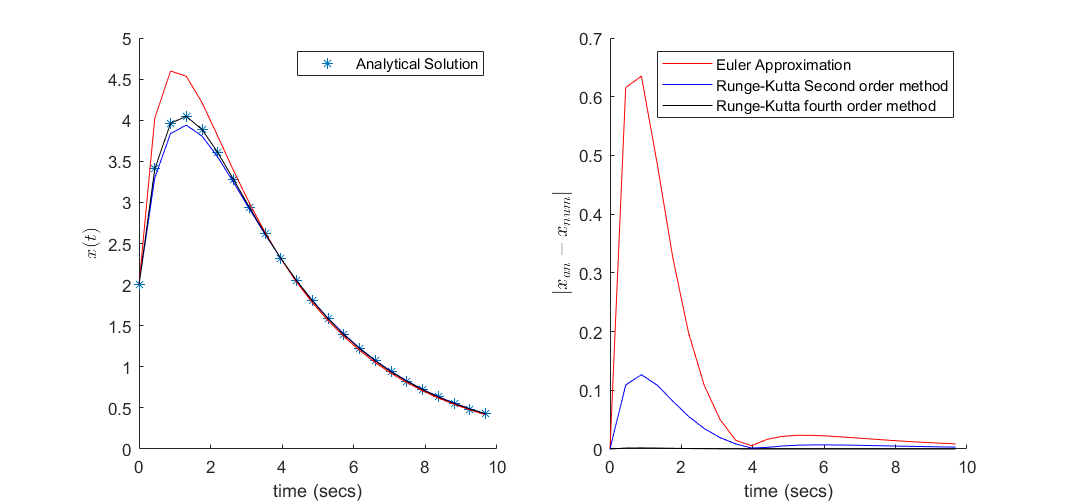


fig = figure();
fig.Position = [488 358.6000 855.4000 403.4000];
subplot(1,2,1)
hold on
%plot(tsamples,x_real,"*", "DisplayName","Analytical Solution")
plot(tsamples,x_real,"*")
plot(tsamples,x_euler,"r")
plot(tsamples,x_rk2, "b")
plot(tsamples, x_rk4, "k")
legend('Analytical Solution')
ylabel("$x(t)$","Interpreter","latex")
xlabel("time (secs)")
legend()
hold off
subplot(1,2,2)
hold on
plot(tsamples,abs(x_real - x_euler),"r",  "DisplayName", "Euler Approximation")
plot(tsamples,abs(x_real - x_rk2),"b",  "DisplayName", "Runge-Kutta Second order method")
plot(tsamples, abs(x_real - x_rk4),"k", "DisplayName", "Runge-Kutta fourth order method")
ylabel("$|x_{an} - x_{num}|$","FontSize",12,"FontWeight","bold","Interpreter","latex")
legend()
xlabel("time (secs)")